**Prepared by Ganesh Dola & Dhaval Polowala - Chapter 3 (Assignment 3.7)**

# Electrical circuits / Van der Pol-Oscillator

The Van der Pol oscillator is a 2nd order ODE with non-linear damping, describing the  behavior of electrical circuits employing vacuum tubes.

             **PDE = y′′ − 𝜇 (1−𝑦^2)𝑦′ +𝑦 = 0** 

             " 𝜇 " is a scalar parameter indicating the strength of the damping.

**Tasks need to perform:**

- Plot the vector field, phase portrait and solution components obtained using an appropriate MATLAB solver. For which values of 𝜇 is this a stiff / non-stiff ODE? 

- Carry out a systematic comparison of different solvers (MATLAB solvers, Euler explicit /  implicit) and explain which solvers are best suited in which case.

%% Van_der_Pol_Oscillator
% This script analyzes the Van der Pol oscillator defined by:
% y"-mu(1 - y^2)y' + y = 0

% y(1) = position (y), y(2) = velocity (y')
% dy/dt = velocity
% dv/dt = acceleration

% Parameters:  
% 'mu' controls damping strength  
% Stiffness occurs when 'mu'= 1

## **1.  Visualization and Stiffness Analysis**

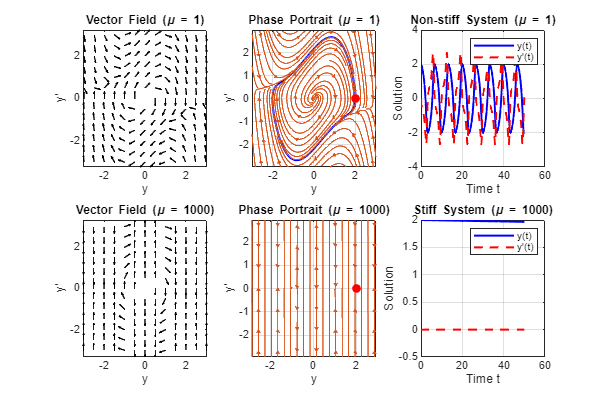

%% Part (a): Visualization and Stiffness Analysis
% Define parameters
mu_nonstiff = 1; % Non-stiff case
mu_stiff = 1000; % Stiff case (μ >> 1)
tspan = [0, 50];    % Simulation time
y0 = [2; 0];        % Initial conditions [y; y'] ; (position,velocity)

% figure position
figure('Position', [100, 100, 1200, 800])

% Non-stiff Case (μ = 1)
subplot(2, 3, 1)
plotVectorField(mu_nonstiff);
title('Vector Field (\mu = 1)')
xlabel('y'), ylabel('y''')

subplot(2, 3, 2)
plotPhasePortrait(mu_nonstiff, tspan, y0);
title('Phase Portrait (\mu = 1)')

subplot(2, 3, 3)
[t, y] = solveODE(@vdpODE, tspan, y0, mu_nonstiff, 'ode45');
plotSolution(t, y, 'Non-stiff System (\mu = 1)')

% Stiff Case (μ = 1000)
subplot(2, 3, 4)
plotVectorField(mu_stiff);
title('Vector Field (\mu = 1000)')
xlabel('y'), ylabel('y''')

subplot(2, 3, 5)
plotPhasePortrait(mu_stiff, tspan, y0);
title('Phase Portrait (\mu = 1000)')

subplot(2, 3, 6)
[t, y] = solveODE(@vdpODE, tspan, y0, mu_stiff, 'ode15s');
plotSolution(t, y, 'Stiff System (\mu = 1000)')


%% Stiffness Conclusion
% *Non-stiff*: 'mu' = 1; (solved efficiently with 'ode45')  
% *Stiff*: 'mu' = 1000; (requires stiff solvers like 'ode15s') 

## **2. Solver Comparison**

%% Part (b): Solver Comparison
% Comparing performance for stiff (μ=1000) and non-stiff (μ=1) systems

% Non-stiff comparison (μ=1)
fprintf('Non-stiff system (μ=1) comparison:\n');

Non-stiff system (μ=1) comparison:


compareSolvers(@vdpODE, tspan, y0, mu_nonstiff);

Solver               Time (s)     Steps
Explicit (ode45)     0.0187     2005
Implicit (ode23s)    0.2316     4503
Implicit (ode15s)    0.0687     1573



% Stiff comparison (μ=1000)
fprintf('Stiff system (μ=1000) comparison:\n');

Stiff system (μ=1000) comparison:


compareSolvers(@vdpODE, tspan, y0, mu_stiff);

Solver               Time (s)     Steps
Explicit (ode45)     0.2704     176841
Implicit (ode23s)    0.0137     149
Implicit (ode15s)    0.0143     106


%% Part (c): Euler Method Comparisons (Explicit & Implicit)

% ------ Non-Stiff Case: μ = 1 ------
fprintf('\nExplicit Euler vs ode45 (μ = 1):\n');


Explicit Euler vs ode45 (μ = 1):


mu_stiff = 1000;
tspan_stiff = [0, 3000];


h = 0.01; % step size
t_euler = 0:h:tspan(2);
y_euler = zeros(2, length(t_euler));
y_euler(:,1) = y0;
tic;
    for i = 1:length(t_euler)-1
        y_euler(:,i+1) = y_euler(:,i) + h * vdpODE(0, y_euler(:,i), mu_nonstiff);
    end
time_euler = toc;

tic;
[t_ode, ~] = solveODE(@vdpODE, tspan, y0, mu_nonstiff, 'ode45');
time_ode = toc;

fprintf('Explicit Euler Time: %.4f s\n', time_euler);

Explicit Euler Time: 0.0074 s


fprintf('ode45 Time: %.4f s\n', time_ode);

ode45 Time: 0.0077 s



% ------ Stiff Case: μ = 1000 ------
fprintf('\nImplicit Euler vs ode15s (μ = 1000):\n');


Implicit Euler vs ode15s (μ = 1000):


h_implicit = 10;
t_implicit = 0:h_implicit:tspan_stiff(2);
y_implicit = zeros(2, length(t_implicit));
y_implicit(:,1) = y0;
tic;
    for i = 1:length(t_implicit)-1
        func = @(y_next) y_next - y_implicit(:,i) - h_implicit * vdpODE(0, y_next, mu_stiff);
        y_implicit(:,i+1) = fsolve(func, y_implicit(:,i), optimset('Display','off'));
    end
time_implicit = toc;

tic;
[t_15s, ~] = solveODE(@vdpODE, tspan_stiff, y0, mu_stiff, 'ode15s');
time_15s = toc;

%printing 
fprintf('Implicit Euler Time: %.4f s\n', time_implicit);

Implicit Euler Time: 1.0123 s


fprintf('ode15s Time: %.4f s\n', time_15s);

ode15s Time: 0.0647 s


## **3. Absolute & Relative Error Analysis for Solvers**

%% Absolute & Relative Error Analysis for Solvers
fprintf('\n--- Absolute & Relative Error Analysis ---\n');


--- Absolute & Relative Error Analysis ---


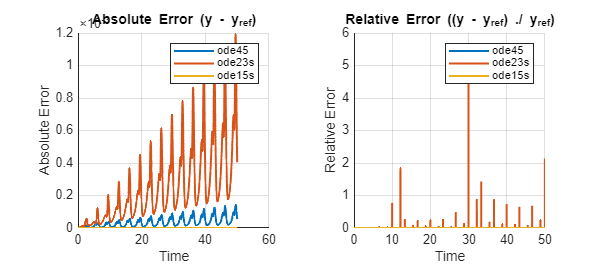


% Reference solution using highly accurate ode15s (Bench mark)
[t_ref, y_ref] = solveODE(@vdpODE, tspan, y0, mu_nonstiff, 'ode15s');
y_ref_interp = @(tq) interp1(t_ref, y_ref, tq, 'spline'); %spline interpolation

solvers = {'ode45', 'ode23s', 'ode15s'};
solverLabels = {'ode45', 'ode23s', 'ode15s'};

% Initialize arrays to hold error metrics
maxAbsError = zeros(1, length(solvers));
maxRelError = zeros(1, length(solvers));

% Plot errors
figure('Name', 'Error Analysis', 'Position', [100, 100, 1100, 500]);
tiledlayout(1,2)

% Absolute Error Plot
nexttile
hold on
title('Absolute Error (y - y_{ref})')
xlabel('Time'), ylabel('Absolute Error'), grid on

% Relative Error Plot
nexttile
hold on
title('Relative Error ((y - y_{ref}) ./ y_{ref})')
xlabel('Time'), ylabel('Relative Error'), grid on

    for i = 1:length(solvers)
        [t_sol, y_sol] = solveODE(@vdpODE, tspan, y0, mu_nonstiff, solvers{i});
        y_ref_vals = y_ref_interp(t_sol);
    
        % Absolute Error
        absErr = vecnorm(y_sol - y_ref_vals, 2, 2); % combined error at each time step
        %norm over two variablees (y , y') at each time
        maxAbsError(i) = max(absErr);
    
        % Relative Error (element-wise division with safe denominator)
        relErr = vecnorm((y_sol - y_ref_vals) ./ (abs(y_ref_vals) + 1e-8), 2, 2);
        maxRelError(i) = max(relErr);
    
        % Plotting the graphs
        nexttile(1)
        plot(t_sol, absErr, 'DisplayName', solverLabels{i}, 'LineWidth', 1.5)
    
        nexttile(2)
        plot(t_sol, relErr, 'DisplayName', solverLabels{i}, 'LineWidth', 1.5)
    end

nexttile(1), legend show
nexttile(2), legend show

nexttile(2)
xlim([0.0 50.0])
ylim([0.00 6.00])


% Print numerical summary
fprintf('%-10s  Max Abs Error    Max Rel Error\n', 'Solver');

Solver      Max Abs Error    Max Rel Error


    for i = 1:length(solvers)
        fprintf('%-10s  %-14.4e  %.4e\n', solverLabels{i}, maxAbsError(i), maxRelError(i));
    end

ode45       1.4386e-04      9.2402e-03
ode23s      1.1942e-03      5.6410e+00
ode15s      4.4409e-16      3.7513e-12


## **4. Helper Function Definitions**

%% Helper Function Definitions
% These functions are now modular and callable from any part of the script

% y(1) = position (y), y(2) = velocity (y')
% dy/dt = velocity
% dv/dt = acceleration

function dydt = vdpODE(~, y, mu)
    % Van der Pol ODE function
    dydt = [y(2); 
            mu*(1 - y(1)^2)*y(2) - y(1)];
end

% Vector field visualization (visualizes the direction field)
% of the Van der Pol oscillator by plotting arrows that represent 
% the direction and rate of change at each point in the phase plane.
%(The arrows represent where the solution would “go” next, and how fast.So every point has its own arrow, based on the Van der Pol equations.)
function plotVectorField(mu)
    [Y1, Y2] = meshgrid(-3:0.5:3, -3:0.5:3);
    dY1 = Y2; % This comes from the first equation
    dY2 = mu*(1 - Y1.^2).*Y2 - Y1; % - This is the Van der Pol differential equation rewritten
    L = sqrt(dY1.^2 + dY2.^2) + 1e-5;  % - Computes the magnitude of each vector
    % (Adds a small number 1e-5 to avoid division by zero)
    quiver(Y1, Y2, dY1./L, dY2./L, 0.5, 'k'); % Plots the normalized vectors as arrows
    axis tight
end

%function "plotPhasePortrait"
function plotPhasePortrait(mu, tspan, y0)
    % Phase portrait with streamlines
    %options = odeset('Refine', 10);
    [~, y] = solveODE(@vdpODE, tspan, y0, mu, 'ode45');
    plot(y(:,1), y(:,2), 'b', 'LineWidth', 1.5)
    hold on
    [Y1, Y2] = meshgrid(linspace(-3,3,20), linspace(-3,3,20));
    streamslice(Y1, Y2, Y2, mu*(1-Y1.^2).*Y2 - Y1)
    plot(y0(1), y0(2), 'ro', 'MarkerFaceColor', 'r')
    axis tight, grid on
    xlabel('y'), ylabel('y''')
end

%function "plotSolution":
function plotSolution(t, y, titleText)
    % Solution components plot
    plot(t, y(:,1), 'b', 'LineWidth', 1.5)
    hold on
    plot(t, y(:,2), 'r--', 'LineWidth', 1.5)
    title(titleText)
    xlabel('Time t')
    ylabel('Solution')
    legend('y(t)', 'y''(t)')
    grid on
end

% function "solveODE":
function [t, y] = solveODE(odefun, tspan, y0, mu, method)
    % ODE solver with automatic method selection
    options = odeset('RelTol', 1e-6, 'AbsTol', 1e-9); % Ref ppt for the "options"
    switch method
        case 'ode45'
            [t, y] = ode45(@(t,y) odefun(t,y,mu), tspan, y0, options);
        case 'ode23s'
            [t, y] = ode23s(@(t,y) odefun(t,y,mu), tspan, y0, options);
        case 'ode15s'
            [t, y] = ode15s(@(t,y) odefun(t,y,mu), tspan, y0, options);
    end
end

% function "compareSolvers":
function compareSolvers(odefun, tspan, y0, mu)
    % Solver comparison function
    solvers = {'ode45', 'ode23s', 'ode15s'};
    solverNames = {'Explicit (ode45)', 'Implicit (ode23s)', 'Implicit (ode15s)'};
    times = zeros(1, 3);
    steps = zeros(1, 3);

        for i = 1:3
            tic;
            [t, ~] = solveODE(odefun, tspan, y0, mu, solvers{i});
            times(i) = toc;
            steps(i) = length(t);
        end

    % Display the results:
    fprintf('%-20s %-12s %s\n', 'Solver', 'Time (s)', 'Steps');
        for i = 1:3
            fprintf('%-20s %-10.4f %d\n', solverNames{i}, times(i), steps(i));
        end
end